# Script to generate figures for "A geostatistical approach to estimate high resolution nocturnal bird migration densities from a weather radar network"

## Load data

load coastlines; warning('off')
addpath('../2-Inference/functions/')
load('../1-Cleaning/data/d_all.mat');
load('../1-Cleaning/data/dc_corr.mat'); 
load('../2-Inference/data/Density_inference.mat'); 
load('../3-Validation/data/Density_crossValidation.mat'); 
load('../3-Validation/data/Density_validationRadars.mat','T_Herzeele','T_Sem','pt_score','pt'); 
load('../4-Estimation/data/Density_estimationMap.mat');
load('../5-Simulation/data/Density_simulationMap_reassemble_ll.mat')

## Figure 1

**Location of weather radar**

Download the DEM as geotiff file on [https://earthexplorer.usgs.gov/metadata/4980/](https://earthexplorer.usgs.gov/metadata/4980/GT30W020N90/)+{files}

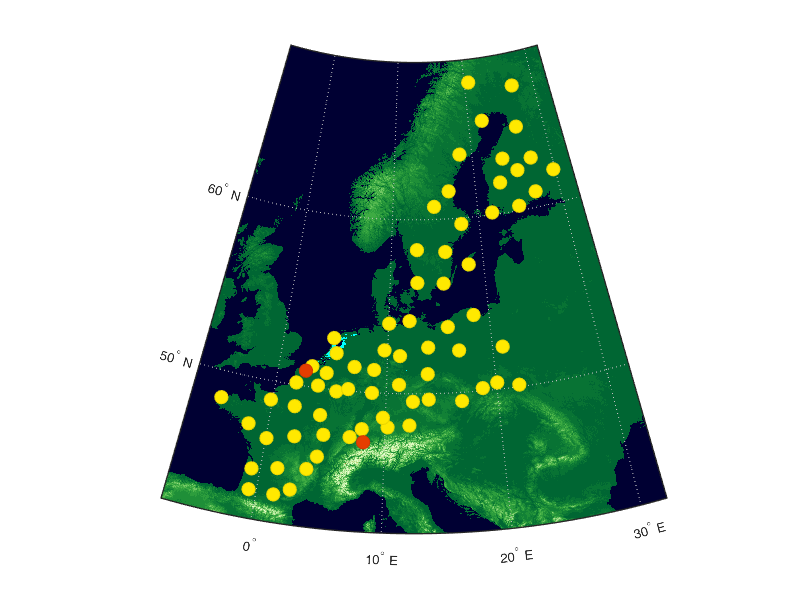

figure('position',[0 0 800 600]);
worldmap([42 69], [-7 32]);  
files={'gt30w020n90','gt30e020n90'}; % ,'gt30e020n40','gt30w020n40'
for i=1:numel(files)
    [X,cmap,R] = geotiffread(['C:\Users\rnussba1\Documents\MATLAB\bin\' files{i}]);
    geoshow(double(X),cmap,'DisplayType','texturemap')
end
demcmap(X)
scatterm([dc.lat],[dc.lon],100,'filled','MarkerFaceColor',[1,.914,0], 'MarkerEdgeColor',[.91,.831,0]);
scatterm([50.884889, 47.126356], [2.544694, 8.193466],100,'filled','MarkerFaceColor',[.898, .239, 0],'MarkerEdgeColor',[.82, .22, 0]);

**Key characteristics  of the radar network**

disp(['Number of radars: ', num2str(numel(dc))]);

Number of radars: 69


for i_d=1:numel(dc)
    [tr(i_d) ,f(i_d)]=mode(diff(dc(i_d).time));
end
disp('Temporal resolution :'); fprintf('%s\t%s\t%s\t%s \n','Duration:',unique(tr)); fprintf('%s\t%d\t\t%d\t\t%d','Count of radar:', histcounts(tr,numel(unique(tr))))

Temporal resolution :
Duration:	00:05:00	00:10:00	00:15:00 
Count of radar:	3		7		59

disp('Scanning distance:'); fprintf('%s\t%d\t%d \n','Distance [km]:',unique([dc.maxrange])); fprintf('%s\t%d\t%d','Count of radar:', histcounts([dc.maxrange],numel(unique([dc.maxrange]))))

Scanning distance:
Distance [km]:	25	40 
Count of radar:	64	5

D = squareform(pdist([[dc.lat]' [dc.lon]'],@lldistkm));
D(eye(numel(dc))==1)=Inf;
disp(['Average distance between closer radars: ', num2str(mean(min(D))) ' (+/- ' num2str(std(min(D))) ')']);

Average distance between closer radars: 143.0161 (+/- 44.9253)


gDdist_sf = reshape(min(pdist2([[dc.lat]' [dc.lon]'], [g.lat2D(:) g.lon2D(:)], @lldistkm)),g.nlat,g.nlon);
gDdist_sf(~(g.mask_water&g.mask_distrad))=nan;
disp(['Distance between node of the grid to its closer radars: ', num2str(nanmean(gDdist_sf(:))) 'km (10-90 quantiles: ' num2str(quantile(gDdist_sf(:),.1)) '-' num2str(quantile(gDdist_sf(:),.9)) ')']);

Distance between node of the grid to its closer radars: 103.3973km (10-90 quantiles: 36.2814-200.9045)


## Figure 2: Space-time variability of bird densities

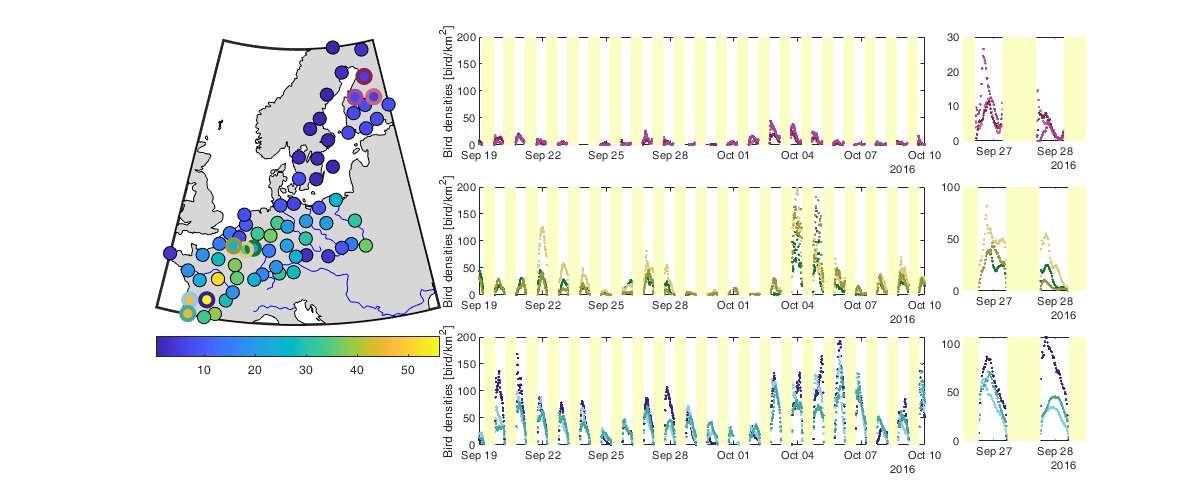

fig1=figure('position',[0 0 1200 500]);clf;
ncol=6; nrow=3;
ax=subplot(nrow,ncol,[1 ncol*(nrow-1)+2]); hold on; 
h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow(ax, 'landareas.shp', 'FaceColor', [215 215 215]./255)
geoshow('worldrivers.shp','Color', 'blue')
S=zeros(numel(dc), 1);
for i=1:numel(dc)
    S(i)=mean(data.dens(data.radar==i));
end
scatterm([dc.lat],[dc.lon],100,S,'filled','MarkerEdgeColor','k'); colorbar('southoutside');

co=get(gca,'ColorOrder');u=0;
co=[204,102,119;136,34,85;170,68,153;17,119,51;221,204,119;153,153,51;51,34,136;136,204,238;68,170,153]/255;
radars={{'fikuo','fiuta','fivim'},{'denhb','bewid','frave'},{'frgre','frbor','frmom'}}; %
for i=1:numel(radars)
    for j=1:numel(radars{i})
        u=u+1;
        i_d=find(strcmp({dc.name},radars{i}{j}));
        subplot(nrow,ncol,ncol*i+[-3 -1]); hold on; box on;
        if j==1
             X=[unique(dc(i_d).sunrise)' unique(dc(i_d).sunset)'];
            for s=1:size(X,1)-1
                fill([X(s,1) X(s,1) X(s+1,2) X(s+1,2)],[0 200 200 0 ],[252, 255, 196]./255,'EdgeColor','none')
            end
        end
        plot(datetime(data.time(data.radar==i_d),'ConvertFrom','datenum'), data.dens(data.radar==i_d),'.','Color',co(u,:));
        ylabel('Bird densities [bird/km^2]')
        xlim([start_date end_date]); ylim([0 200])
        subplot(nrow,ncol,ncol*i); hold on; box on
        plot(datetime(data.time(data.radar==i_d),'ConvertFrom','datenum'), data.dens(data.radar==i_d),'.','Color',co(u,:));
        xlim(datetime({'26/09/2016 12:00' '28/09/2016 12:00'}) );
        if j==numel(radars{i})
            yl=get(gca,'ylim');
            for s=1:size(X,1)-1
                fill([X(s,1) X(s,1) X(s+1,2) X(s+1,2)],[yl fliplr(yl)],[252, 255, 196]./255,'EdgeColor','none')
            end
        end
        scatterm(ax,dc(i_d).lat,dc(i_d).lon,100,'MarkerEdgeColor',co(u,:),'linewidth',3);
    end
end

## Figure 3: Mathematical model

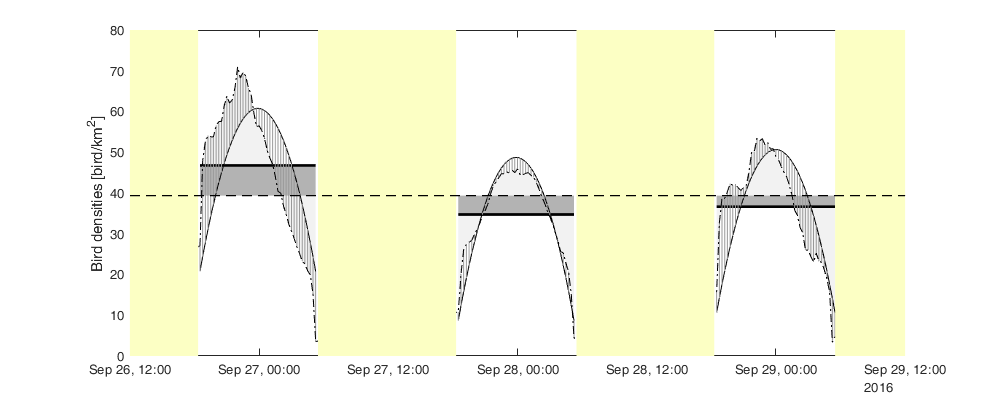

fig2=figure('position',[0 0 1000 400]);clf; clf; hold on; box on;
i_r=find(strcmp({dc.name},'frmom'));
X=[unique(dc(i_r).sunrise)' unique(dc(i_r).sunset)'];

t=9:11;

poly = [1^2 1 1;44^2 44 1;22^2 22 1] \ [-30;-30;10];

mu=mean(data.dens(any(data.day==t,2) & data.radar==i_r));

for i_t=1:numel(t)
    d_d=data.dens(data.day==t(i_t) & data.radar==i_r);
    M=mean(d_d);
    d_a=datetime(data.time(data.day==t(i_t) & data.radar==i_r),'ConvertFrom','datenum');
    fill([d_a' d_a(end) d_a(1)],[ d_d ; M ;M],[.95 .95 .95],'edgecolor','none')
    fill([d_a(1) d_a(end) d_a(end) d_a(1)],[ mu;mu ; M ;M],[.70 .70 .70],'edgecolor','none')
    plot([d_a(1) d_a(end)],[M M],'-k','LineWidth',2);
    plot(linspace(d_a(1),d_a(end),44),M+4+[(1:44)'.^2 (1:44)' ones(44,1)]*poly,'k')
    c_a=interp1(linspace(d_a(1),d_a(end),44),M+4+[(1:44)'.^2 (1:44)' ones(44,1)]*poly,d_a);
    for ii=1:numel(c_a)
        plot([d_a(ii) d_a(ii)],[c_a(ii) d_d(ii)],'Color',[.6 .6 .6])
    end
end
plot(datetime(data.time(data.radar==i_r),'ConvertFrom','datenum'), data.dens(data.radar==i_d),'-.k')
for s=1:size(X,1)-1
    fill([X(s,1) X(s,1) X(s+1,2) X(s+1,2)],[0 80 80 0 ],[252, 255, 196]./255,'EdgeColor','none')
end
plot([start_date end_date],[mu mu],'--k','LineWidth',1)
xlim(datetime({'26/09/2016 12:00' '29/09/2016 12:00'}) ); ylabel('Bird densities [bird/km^2]');

## Cross-validation result

Score cross-validation

disp(['Normalized error of estimation- mean: ' num2str(mean(cv.nee)) ' and variance: ' num2str(var(cv.nee))])

Normalized error of estimation- mean: 0.0098186 and variance: 1.0794


cv

cv = struct with fields:
     denst_est: [50436×1 double]
     denst_sig: [50436×1 double]
      dens_est: [50436×1 double]
    rmse_denst: 0.1403
     rmse_dens: 17.6655
           nee: [50436×1 double]
       rmse_nn: 23.1713
        rmse_l: 18.4955
        rmse_n: 17.9504
       r2_dens: 0.5855
         r2_nn: 0.2869
          r2_l: 0.5456
          r2_n: 0.5720


## Figure 4: Validation bird radar

Displays score

pt_score.her

ans = struct with fields:
        nee: [1354×1 double]
      nee_m: 0.4853
    nee_var: 0.7718
          n: 168
       rmse: 9.2235
    rmse_nn: 9.7975
     rmse_l: 8.9119
     rmse_n: 8.9495
    r2_dens: 0.8698
      r2_nn: 0.8531
       r2_l: 0.8784
       r2_n: 0.8774


pt_score.sem

ans = struct with fields:
        nee: [1463×1 double]
      nee_m: -0.6810
    nee_var: 1.4520
          n: 231
       rmse: 19.7296
    rmse_nn: 24.2551
     rmse_l: 21.6694
     rmse_n: 18.9431
    r2_dens: 0.7270
      r2_nn: 0.5875
       r2_l: 0.6707
       r2_n: 0.7484


Figure

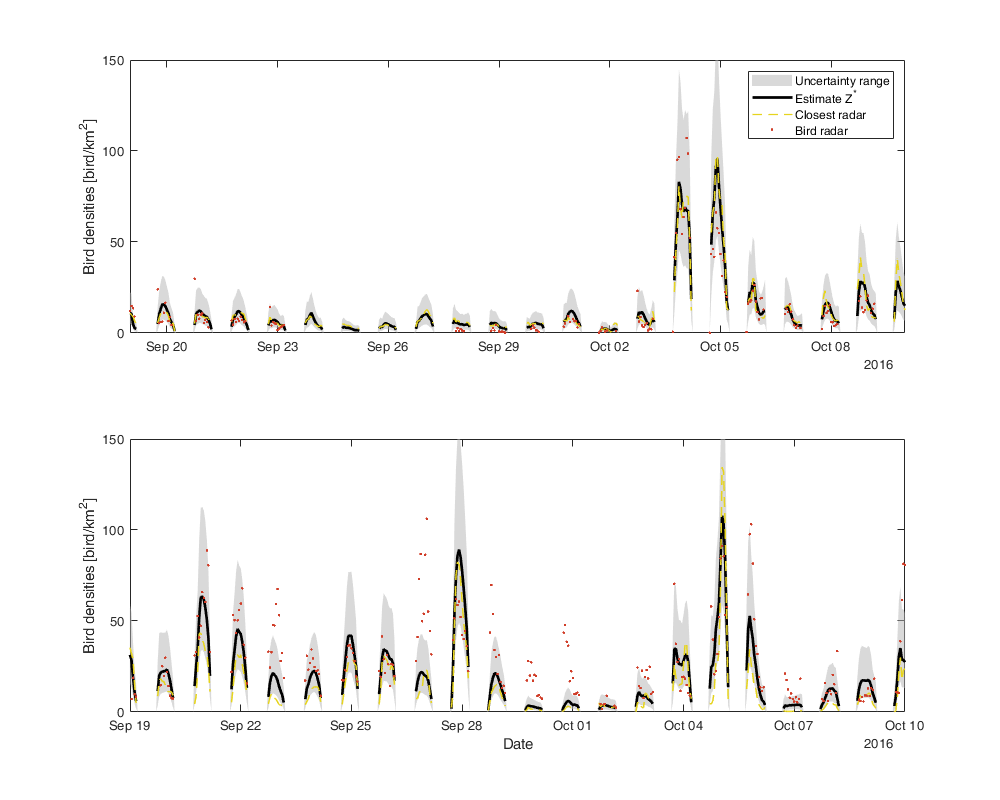

figure('position',[0 0 1000 800]); 
subplot(2,1,1); hold on
tmp1 = ( T_Herzeele.denst_est+norminv(.1).*T_Herzeele.denst_sig ).^(1/pow);
tmp2 = ( T_Herzeele.denst_est+norminv(.9).*T_Herzeele.denst_sig ).^(1/pow);
tmp1(isnan(tmp1))=0;
tmp2(isnan(tmp2))=0;
fill([T_Herzeele.Tint' fliplr(T_Herzeele.Tint')]', [tmp2 ; flipud(tmp1)],[.7 .7 .7],'EdgeColor','none','FaceAlpha',.5);
plot(T_Herzeele.Tint,T_Herzeele.dens_est,'k','linewidth',2);
plot(T_Herzeele.Tint,T_Herzeele.interpo_nn,'--','Color',[230 212 30]/255,'linewidth',1);
plot(T_Herzeele.Tint(T_Herzeele.is_night),T_Herzeele.dens(T_Herzeele.is_night),'.','Color',[208 60 39]/255,'linewidth',2);
xlim([start_date end_date]); ylabel('Bird densities [bird/km^2]'); xticklabels=[]; box on
legend('Uncertainty range','Estimate Z^*','Closest radar','Bird radar');ylim([0 150])

subplot(2,1,2); hold on;
tmp1 = ( T_Sem.denst_est+norminv(.1).*T_Sem.denst_sig ).^(1/pow);
tmp2 = ( T_Sem.denst_est+norminv(.9).*T_Sem.denst_sig ).^(1/pow);
tmp1(isnan(tmp1))=0;
tmp2(isnan(tmp2))=0;
fill([T_Sem.Tint' fliplr(T_Sem.Tint')]', [tmp2 ; flipud(tmp1)],[.7 .7 .7],'EdgeColor','none','FaceAlpha',.5);
plot(T_Sem.Tint,T_Sem.dens_est,'k','linewidth',2);
plot(T_Sem.Tint,T_Sem.interpo_nn,'--','Color',[230 212 30]/255,'linewidth',1);
plot(T_Sem.Tint(T_Sem.is_night),T_Sem.dens(T_Sem.is_night),'.','Color',[208 60 39]/255,'linewidth',2);
xlim([start_date end_date]); ylabel('Bird densities [bird/km^2]'); box on; xlabel('Date'); ylim([0 150])

## Figure 5: Nightly variation

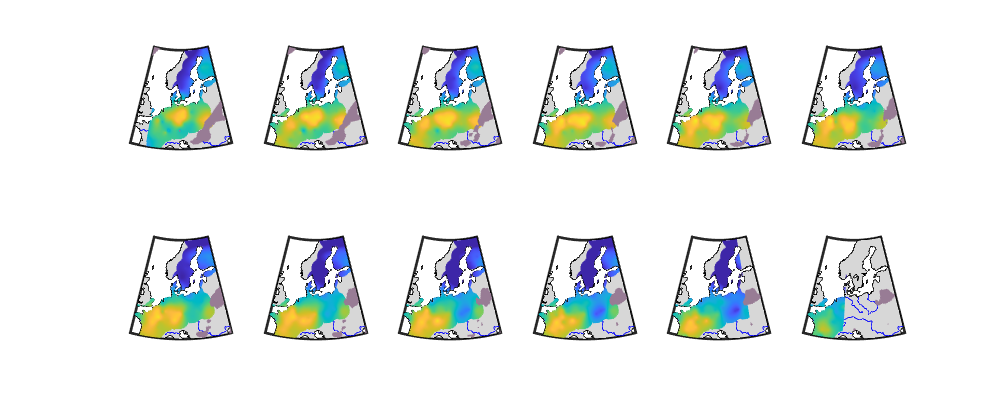

it=1512+(1:4:(4*12));

figure('position',[0 0 1000 400]); 
for i_t=1:length(it)
    subplot(2,6,i_t)
    h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [215 215 215]./255)
    geoshow('worldrivers.shp','Color', 'blue')
    surfm(g.lat2D,g.lon2D,log10(gd.dens_est(:,:,it(i_t))));
    geoshow(g.lat2D,g.lon2D,ones(size(g.lat2D)),'FaceColor',[152, 124, 149]/255,'FaceAlpha','flat','AlphaData',double(~g.mask_rain(:,:,it(i_t))));
    caxis(log10([1 250])); 
end

## Figure 6: realization at peak migration

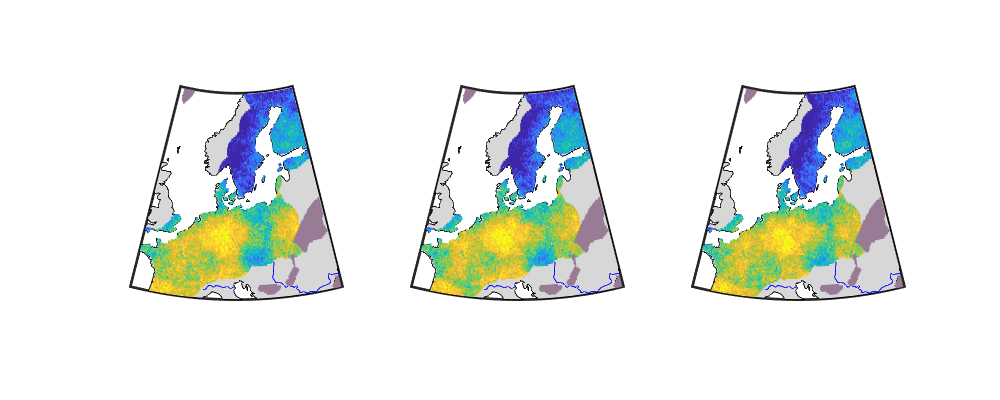

ans = 124.7059

ans = 125.7105

ans = 122.4551

figure('position',[0 0 1000 400]); hold on

col=colormap;
n=3;
i=1525;
for u=1:n
    tmp=nan(g.nlat,g.nlon);
    tmp(g.latlonmask)=real_dens_ll(:,i,u);

    subplot(1,n,u);
    h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [215 215 215]./255)
    geoshow('worldrivers.shp','Color', 'blue')
    surfm(g.lat2D,g.lon2D,log10(tmp)); 
    surfm(g.lat2D,g.lon2D,ones(size(g.lat2D)),'FaceColor',[152, 124, 149]/255,'FaceAlpha','flat','AlphaData',double(~g.mask_rain(:,:,i)));
    caxis(log10([1 250]))
    
    sum(nansum( tmp .* area(:,:,i) ))/1000000
end

## Figure 7: Integral global

fr=reshape([2.14007280533,47.2536732633,0 -2.53965472699,47.2980540996,0 -2.36708190132,47.501526979,0 -2.83187285057,47.497282048,0 -2.70028183186,47.6370821351,0 -3.1250728303,47.5954091564,0 -3.13263682738,47.4766640749,0 -3.21694569779,47.6505542004,0 -3.98221781844,47.8897182295,0 -4.3673639235,47.8087451889,0 -4.72223677349,48.0391730956,0 -4.28291775751,48.1165271657,0 -4.54659969165,48.1744362261,0 -4.56535487061,48.3227541709,0 -4.76062672833,48.3349912466,0 -4.77666382372,48.5111091144,0 -4.3541639347,48.6741641214,0 -3.58242685212,48.6777732013,0 -3.53666383995,48.825827116,0 -3.22610879437,48.8695819918,0 -2.68528191317,48.5016640506,0 -2.30721784576,48.6761090582,0 -1.9761088648,48.5130451664,0 -1.98805492088,48.6869451826,0 -1.36889077238,48.6436090667,0 -1.5625727507,48.7489539996,0 -1.60971777107,49.2150002227,0 -1.94208185822,49.7215912203,0 -1.26416392105,49.6841641785,0 -1.10958184477,49.3694361186,0 -0.228336873277,49.2836091178,0 0.424718159704,49.4516642653,0 0.075836191201,49.5225641023,0 0.185973225768,49.7040271097,0 1.46110914193,50.1241641403,0 1.62500032753,50.8777731779,0 2.54166319863,51.0911090428,0 2.65055417947,50.8161090248,0 3.15857311809,50.7843642428,0 3.29708205679,50.5243001057,0 4.16500013748,50.2830541795,0 4.1492361245,49.9783731717,0 4.51055415514,49.9474912228,0 4.82472716541,50.1675641263,0 4.86847332403,49.8022182559,0 5.47278222549,49.508882154,0 5.80788233348,49.5450452048,0 6.36217306579,49.459391039,0 6.72923622052,49.1676360994,0 7.42555411159,49.1764540292,0 8.22608219347,48.9644181974,0 7.80221806588,48.5758269625,0 7.57838219081,48.1172002325,0 7.58827317186,47.5844821721,0 7.38541820631,47.4333271207,0 6.99055429033,47.4972181779,0 6.9716631569,47.2919361484,0 6.12868207642,46.5880540927,0 6.11555417199,46.2615269953,0 5.96700924531,46.2072912201,0 6.13326328943,46.149782144,0 6.29555420208,46.3941640755,0 6.73778224139,46.4474910848,0 6.78347316919,46.1547182468,0 7.03805420048,45.9319361446,0 6.79934514109,45.7886641056,0 7.14694518132,45.4305451121,0 7.12778213895,45.2593001476,0 6.62396320438,45.1157270306,0 7.03166316693,44.8313820287,0 6.85278228855,44.5408360948,0 6.97639122085,44.2841641139,0 7.66221815424,44.1708270363,0 7.53193622116,43.782045197,0 7.43929121274,43.7575269566,0 7.40280026189,43.758818105,0 7.39160924765,43.7275452242,0 6.63639121989,43.3111000867,0 6.64166310173,43.1850000528,0 6.16528215965,43.0505539902,0 5.03958216648,43.347909047,0 5.23152724682,43.4658270023,0 5.02416332027,43.5526361944,0 4.81505411384,43.3992180292,0 4.7075002142,43.5720820422,0 4.65278214429,43.3597181428,0 3.96471824858,43.5408361511,0 3.08139121233,43.0694451237,0 2.96131810207,42.8422180982,0 3.17765418545,42.4368092451,0 2.02055424179,42.3526361615,0 1.72360906008,42.5094360893,0 1.73860914641,42.6163911858,0 1.44583614083,42.6019451433,0 0.71610915708,42.8588821599,0 0.675509229642,42.6884820912,0 -0.555836774358,42.7800000689,0 -0.754099798053,42.9643731056,0 -1.4395178622,43.0493731477,0 -1.38513691244,43.2525640599,0 -1.78087288163,43.3599270198,0 -1.44389086874,43.6405450923,0 -1.20860900193,44.6258272521,0 -1.04062694464,44.6749270999,0 -1.24583688971,44.6753450216,0 -1.08944583108,45.5586091936,0 -0.53992674862,44.8956180849,0 -0.781526894062,45.4665180614,0 -1.23885493198,45.7062180293,0 -1.07097278698,45.9039451142,0 -1.11463680295,46.3165821853,0 -1.78639085614,46.4883270466,0 -2.12541788578,46.8309730467,0 -1.9858727762,47.0369271372,0 -2.170836737,47.1266641281,0 -2.14007280533,47.2536732633,0],3,[])';
de=reshape([9.44535423355,54.8254001391,0 9.97200916046,54.7607542078,0 10.0325001824,54.555273192,0 9.86603608777,54.4572912581,0 10.9794451934,54.3805540962,0 11.0939542286,54.2054821222,0 10.7622181137,54.0565271528,0 10.8185361213,53.8900541734,0 11.0947181553,54.0136091263,0 11.4127731602,53.9197180641,0 12.5269451866,54.4741541386,0 12.9215271354,54.427464088,0 12.4638911464,54.3951360931,0 12.3743730907,54.2624272638,0 13.0238911282,54.3997181443,0 13.4545821483,54.0970821533,0 13.7108273227,54.1708269758,0 13.8085361741,53.8547821189,0 14.2756271176,53.6990641271,0 14.3916911635,53.1441641981,0 14.1491631414,52.8627820313,0 14.6395822626,52.5729822544,0 14.5344452009,52.3962451316,0 14.7607632928,52.0698642146,0 14.6009732048,51.8200640533,0 15.0338182064,51.2866539829,0 14.8283361848,50.8658271218,0 14.3062452041,51.0524911002,0 14.3113911898,50.8822181011,0 12.985554147,50.4183272007,0 12.5154180581,50.3924911575,0 12.3230542179,50.206664196,0 12.0937002006,50.3225361287,0 12.5459731127,49.9095822216,0 12.4555543378,49.6955451266,0 12.6744452253,49.4250002578,0 13.8336092964,48.7736090326,0 13.7260000762,48.5155910857,0 13.4432271841,48.5602361196,0 13.3950002276,48.3661001774,0 12.7597181822,48.1217271308,0 13.0088912095,47.8541642078,0 12.9139542535,47.7250000853,0 13.1001361048,47.642918119,0 13.0125001218,47.4697910819,0 12.7369452217,47.6827091928,0 11.104027097,47.3965270453,0 10.4818002011,47.5865181364,0 10.1733361051,47.2747182105,0 10.2317361774,47.3737450324,0 9.95500009958,47.5397181151,0 9.56672704172,47.5404542139,0 8.56291802597,47.80666413,0 8.40694522432,47.7018001508,0 8.5764180869,47.5913731023,0 7.58827317186,47.5844821721,0 7.57838219081,48.1172002325,0 7.80221806588,48.5758269625,0 8.22608219347,48.9644181974,0 7.42555411159,49.1764540292,0 6.72923622052,49.1676360994,0 6.36217306579,49.459391039,0 6.52402711365,49.8077001882,0 6.2341631314,49.8975000434,0 6.13440926324,50.1278451369,0 6.39820016212,50.3231729857,0 6.27041821549,50.6198541375,0 6.01180012435,50.7572730935,0 6.0808361613,50.9147180926,0 5.86500014228,51.0453451925,0 6.09750005541,51.1311001088,0 6.22208212668,51.4673542372,0 5.9636092101,51.8066642399,0 6.82895421414,51.9757540495,0 6.73639118073,52.0766641174,0 7.05309116718,52.2377641293,0 7.06298214823,52.3909641973,0 6.68958227468,52.5505541255,0 7.05347321433,52.6495821208,0 7.20836307409,53.2428091404,0 7.3370821175,53.3230539613,0 7.01500011101,53.409854101,0 7.2958362806,53.6852730465,0 8.0143092182,53.708327136,0 8.09777319277,53.4444452096,0 8.28603627067,53.4208910558,0 8.33221821036,53.6152732583,0 8.49206311602,53.5558822774,0 8.48410014035,53.6863181022,0 8.65902710735,53.8926361349,0 9.0960452909,53.8666731897,0 9.28340010577,53.8555452074,0 9.82906317748,53.5417000972,0 9.27600927881,53.8818912055,0 8.88305408982,53.9611090756,0 9.01721818518,54.0850003104,0 8.82736304858,54.1516642687,0 8.88360913945,54.2941641668,0 8.60048219571,54.3263821911,0 9.01124524096,54.5034639777,0 8.54560922823,54.8706091075,0 8.28055433834,54.7749912056,0 8.40805415011,55.0565270965,0 8.42041812788,54.9196450852,0 8.66454508186,54.9130911075,0 9.44535423355,54.8254001391,0],3,[])';
ch=reshape([10.4712361532,46.8713542065,0 10.4575272152,46.5425001251,0 10.0513911482,46.5415271538,0 10.1363911903,46.2306911469,0 9.94694525824,46.3795820785,0 9.54486301486,46.3062451194,0 9.29378226635,46.5008271465,0 9.03666319477,45.8377731735,0 8.44500007067,46.2472182483,0 8.44145419034,46.4620821342,0 7.85574506735,45.9190541652,0 7.03805420048,45.9319361446,0 6.78347316919,46.1547182468,0 6.73778224139,46.4474910848,0 6.29555420208,46.3941640755,0 6.13326328943,46.149782144,0 5.96700924531,46.2072912201,0 6.11555417199,46.2615269953,0 6.12868207642,46.5880540927,0 6.9716631569,47.2919361484,0 6.99055429033,47.4972181779,0 7.38541820631,47.4333271207,0 7.58827317186,47.5844821721,0 8.5764180869,47.5913731023,0 8.40694522432,47.7018001508,0 8.56291802597,47.80666413,0 9.56672704172,47.5404542139,0 9.67034513489,47.3906910614,0 9.5335732618,47.2745450404,0 9.4746360771,47.0574540828,0 9.59863627664,47.0638360639,0 10.1094450479,46.8502732171,0 10.3907631769,47.0025641839,0 10.4712361532,46.8713542065,0],3,[])';
nl=reshape([7.20836307409,53.2428091404,0 7.05347321433,52.6495821208,0 6.68958227468,52.5505541255,0 7.06298214823,52.3909641973,0 7.05309116718,52.2377641293,0 6.73639118073,52.0766641174,0 6.82895421414,51.9757540495,0 5.9636092101,51.8066642399,0 6.22208212668,51.4673542372,0 6.09750005541,51.1311001088,0 5.86500014228,51.0453451925,0 6.0808361613,50.9147180926,0 6.01180012435,50.7572730935,0 5.63881817249,50.8488820987,0 5.84713612726,51.1531911176,0 5.23897322671,51.2622820907,0 5.03847307305,51.4869450919,0 4.25236303814,51.3751450878,0 3.4442362581,51.5293731125,0 3.83500008231,51.6066641506,0 4.28360926452,51.4480540669,0 3.9978452064,51.590136211,0 4.20943612674,51.6740911974,0 3.86798203321,51.8121451664,0 4.5743731279,52.4544730397,0 5.42250019403,52.2490181754,0 5.87805411832,52.5094360288,0 5.85357309364,52.6059452622,0 5.60055411384,52.6581911736,0 5.71835421958,52.8380182012,0 5.37080011219,52.8802001291,0 5.36986301541,53.0704091496,0 5.10027318061,52.94805415,0 5.30319117807,52.7048542346,0 5.04959116473,52.6415732123,0 5.02971817516,52.6240910768,0 5.07805409634,52.4161090687,0 4.58200904172,52.4770822177,0 4.73881802204,52.9566642086,0 5.09444507568,52.9591641951,0 5.98166315904,53.3988912421,0 6.74194519743,53.4658272771,0 7.20836307409,53.2428091404,0],3,[])';
se=reshape([11.4291911293,58.9876360087,0 11.6240272957,58.9069360506,0 11.7518000222,59.0951362642,0 11.6670091924,59.5935731787,0 11.8991002363,59.6997182481,0 11.8159631559,59.8461001408,0 12.4945092329,60.1130451499,0 12.5909730364,60.5218000587,0 12.2162181444,60.9987451029,0 12.6378272048,61.0575361072,0 12.8561092308,61.3625000881,0 12.1244451892,61.7286092146,0 12.2937450493,62.2670821221,0 12.047500156,62.5900001396,0 12.0288911575,62.8924911238,0 12.1686091019,63.0158273089,0 11.936391156,63.2722181608,0 12.1466632676,63.5895731091,0 12.9380540692,64.0533272169,0 13.9850002145,64.0155451177,0 14.1506911624,64.1798450049,0 14.1163910734,64.4705540507,0 13.66826318,64.580200241,0 14.4930540218,65.3136001747,0 14.633191229,65.8218001624,0 14.5070821427,66.1236001425,0 15.468054101,66.2838731958,0 15.3627820907,66.4800001752,0 16.3538821295,67.0177730262,0 16.3613820889,67.2377822272,0 16.0880540929,67.4054001746,0 16.7269450506,67.8991541198,0 17.2736090892,68.0905449887,0 17.8841631791,67.9455451042,0 18.1552822083,68.1661091871,0 18.0995361818,68.508927184,0 19.9523632599,68.3427631615,0 20.2042360983,68.4708911131,0 19.9563912673,68.5438820672,0 20.3502731595,68.7866540027,0 20.0969452228,69.0422182313,0 20.58092721,69.0603001758,0 22.0486091889,68.4815181929,0 22.826663209,68.3859631553,0 23.6597911947,67.9458911091,0 23.488818139,67.8709630971,0 23.4308271036,67.4797821894,0 23.7651361275,67.4168733237,0 23.5733273369,67.1570091788,0 24.0007631611,66.8022821739,0 23.6625002258,66.3122092253,0 24.1670091586,65.8140272883,0 23.077354199,65.7008271711,0 22.6758271729,65.9022181534,0 22.6793001307,65.7604731295,0 22.368191209,65.8591542817,0 22.2490541897,65.6324911907,0 22.4000001963,65.536800031,0 21.7658272443,65.7121450873,0 22.1943733354,65.5422822986,0 21.4712452564,65.3837453051,0 21.6593001278,65.2458271229,0 21.264863186,65.3382542019,0 21.6193732672,65.1513731322,0 21.0393732261,64.8238180782,0 21.303400327,64.761654196,0 21.1191632449,64.6843629902,0 21.5850002557,64.4397091498,0 20.9637453252,64.1427002656,0 20.7740273166,63.8670821661,0 19.7050002208,63.4319361644,0 19.4258271884,63.54631813,0 19.0625001832,63.1769362056,0 18.8966632226,63.2731911321,0 18.2891631629,62.9972181427,0 18.5752001358,62.9618000755,0 18.2040271663,62.7773541163,0 17.7005542367,62.9927090141,0 18.0463912274,62.5952731949,0 17.3308271455,62.4877732747,0 17.6488821504,62.2317272544,0 17.3508272047,61.9434731005,0 17.4951731332,61.634582198,0 17.1487822663,61.7172820782,0 17.2645452343,61.6853731786,0 17.0986091996,61.6027732106,0 17.2196542754,61.434654193,0 17.1052731479,61.3999271299,0 17.1525001433,60.9427732679,0 17.2752732322,60.6761090526,0 17.6879181824,60.4973542381,0 17.960973096,60.5920821494,0 18.5996181286,60.2356182466,0 18.3170822767,60.3081911114,0 18.4216631152,60.1872182876,0 18.8163910768,60.0963820939,0 19.0705540187,59.8897182239,0 18.8647181131,59.798045181,0 19.079654251,59.7674270945,0 18.2420632372,59.400454129,0 18.0913911511,59.3344449649,0 17.9570542209,59.3582631487,0 17.7827731634,59.3891630348,0 17.8177091036,59.586454093,0 17.6523730455,59.6360912209,0 17.7313912586,59.4448540761,0 17.3828452368,59.6523541247,0 17.4044452337,59.4691631041,0 16.5586091093,59.6098541875,0 16.0324631316,59.4901631244,0 16.8777732077,59.3819361579,0 16.6954181981,59.4704820804,0 16.8367360802,59.4896451227,0 17.2869452001,59.2590450518,0 18.0937092503,59.3156182045,0 18.477218202,59.4352732254,0 18.6431540691,59.321873116,0 18.2772181127,59.3108271086,0 18.311391132,59.1325001064,0 17.8947180068,58.8588911491,0 17.6662450953,59.1673540716,0 17.6291001883,58.9102001313,0 17.3500002462,58.7522180198,0 16.1936092439,58.6274911093,0 16.9336092558,58.4883272086,0 16.4228450763,58.4777730514,0 16.7700002051,58.3672182628,0 16.8258360856,58.1766630696,0 16.6202092247,57.9870092663,0 16.7636091715,57.8812360182,0 16.5062091386,57.9919731971,0 16.6951731112,57.7417001287,0 16.419236164,57.8890912026,0 16.7113912557,57.7026361012,0 16.6658272299,57.4085362404,0 16.465973321,57.2705540205,0 16.5844451525,57.0466631601,0 16.0034731459,56.2130542209,0 15.8655541255,56.0922180222,0 14.6926361894,56.1581911441,0 14.7383361697,56.0108272275,0 14.5551360966,56.0562452406,0 14.2172181604,55.8302731536,0 14.3659360896,55.5428451201,0 14.1935451512,55.3861451045,0 13.3755542122,55.3400002128,0 12.9822181495,55.400554099,0 12.9211821363,55.5724272034,0 13.0611091253,55.6807641405,0 12.4600730218,56.2966642082,0 12.7992363412,56.2259001581,0 12.6243001541,56.4183271979,0 12.9011091545,56.4572182229,0 12.8802090465,56.6429821525,0 12.3488912668,56.916809207,0 12.0950000662,57.4269361943,0 11.9027731862,57.4243091382,0 11.8877821524,57.6938822092,0 11.7018730482,57.6999270701,0 11.8787001926,58.2021631661,0 11.7980542139,58.3183271243,0 11.7277362487,58.3284001603,0 11.5286092184,58.2307541732,0 11.2013912845,58.3994361194,0 11.1133362063,59.003609234,0 11.2199452978,59.0534730085,0 11.320000244,59.1002730297,0 11.4291911293,58.9876360087,0],3,[])';
pl=reshape([22.5580542245,49.0794361818,0 21.6126362287,49.4365272187,0 20.9136091389,49.2961090501,0 20.3605540667,49.3930541425,0 20.073363241,49.1778730854,0 19.7834731073,49.2001999609,0 19.7780181647,49.4074911325,0 19.4755543379,49.6000001473,0 19.1595822359,49.4002731404,0 18.8512452096,49.5173542465,0 18.578745178,49.9122181625,0 17.6577731704,50.1080541223,0 17.7244451754,50.3190271287,0 16.8909731965,50.4386730972,0 17.002218151,50.2169451031,0 16.6400002392,50.1088911392,0 16.2190271977,50.4102731975,0 16.447363149,50.5788180158,0 16.3320092179,50.6640272702,0 15.379718229,50.7794450715,0 15.1769450708,51.0147180534,0 14.8283361848,50.8658271218,0 15.0338182064,51.2866539829,0 14.6009732048,51.8200640533,0 14.7607632928,52.0698642146,0 14.5344452009,52.3962451316,0 14.6395822626,52.5729822544,0 14.1491631414,52.8627820313,0 14.3916911635,53.1441641981,0 14.2756271176,53.6990641271,0 14.5250001371,53.6605541434,0 14.6141631353,53.8163822734,0 14.2188911883,53.869018111,0 14.2255541308,53.9286001993,0 16.1747182781,54.2591641889,0 16.5436091906,54.5447181965,0 17.918891248,54.8266641301,0 18.740000255,54.6852731578,0 18.4061093204,54.7381911302,0 18.5952092475,54.4277730449,0 18.8437452502,54.3517999772,0 19.6272540453,54.4632730872,0 19.6511092771,54.4558271073,0 19.2533271177,54.2781911092,0 19.7970092104,54.4375451706,0 22.7858822325,54.3638360549,0 23.3561091421,54.235409037,0 23.5040363225,53.9470452478,0 23.9352733398,52.7174911271,0 23.1654002248,52.2822732087,0 23.6386091194,52.0794361804,0 23.60463626,51.5276910321,0 24.1434731097,50.8595732162,0 23.954382235,50.7917000845,0 24.1113821551,50.5669361651,0 22.6784632815,49.5694360402,0 22.7038091509,49.1698911666,0 22.8860733007,49.0029181228,0 22.5580542245,49.0794361818,0],3,[])';
be=reshape([2.54166319863,51.0911090428,0 3.37086325679,51.373854107,0 3.43986325156,51.2447821855,0 3.89541801404,51.2056910007,0 4.23890019286,51.3504270229,0 4.32770008701,51.290127276,0 4.25236303814,51.3751450878,0 5.03847307305,51.4869450919,0 5.23897322671,51.2622820907,0 5.84713612726,51.1531911176,0 5.63881817249,50.8488820987,0 6.01180012435,50.7572730935,0 6.27041821549,50.6198541375,0 6.39820016212,50.3231729857,0 6.13440926324,50.1278451369,0 5.9730542739,50.170000075,0 5.74777319107,49.9074911044,0 5.89916310333,49.6627732262,0 5.80788233348,49.5450452048,0 5.47278222549,49.508882154,0 4.86847332403,49.8022182559,0 4.82472716541,50.1675641263,0 4.51055415514,49.9474912228,0 4.1492361245,49.9783731717,0 4.16500013748,50.2830541795,0 3.29708205679,50.5243001057,0 3.15857311809,50.7843642428,0 2.65055417947,50.8161090248,0 2.54166319863,51.0911090428,0],3,[])';
fi=reshape([24.1670091586,65.8140272883,0 23.6625002258,66.3122092253,0 24.0007631611,66.8022821739,0 23.5733273369,67.1570091788,0 23.7651361275,67.4168733237,0 23.4308271036,67.4797821894,0 23.488818139,67.8709630971,0 23.6597911947,67.9458911091,0 22.826663209,68.3859631553,0 22.0486091889,68.4815181929,0 20.58092721,69.0603001758,0 21.0634732095,69.036800169,0 21.0302731615,69.2105452877,0 21.320827142,69.3261091017,0 21.6819451804,69.2847180902,0 22.3983271684,68.7111090827,0 23.1963911384,68.6298540749,0 23.9763911012,68.8324911109,0 24.934918226,68.5808092123,0 25.7611091809,68.989163131,0 25.7133361883,69.2552630765,0 25.983327181,69.7043000711,0 26.4768001648,69.9363822302,0 27.9106911716,70.0886091593,0 28.3797183347,69.8275001341,0 29.1275002732,69.6858181422,0 29.2984731612,69.4853360934,0 28.825418326,69.2361632337,0 28.9573362389,69.0516180328,0 28.4355542152,68.9026360737,0 28.8173542645,68.8470001854,0 28.4598541908,68.5348542546,0 28.6950002708,68.1954091356,0 29.3569453179,68.0824911532,0 30.0286091818,67.6947181597,0 29.075136177,66.9036001052,0 29.9037451434,66.1338822231,0 30.134927086,65.7088820124,0 29.8188820615,65.6533180408,0 29.6020452432,65.2444360623,0 29.869445222,65.1199911189,0 29.6211821341,65.0523540216,0 29.6408271359,64.9209631628,0 30.1427730503,64.7720732369,0 30.2068731521,64.663327263,0 29.9764542979,64.5789451348,0 30.0615272626,64.4053451907,0 30.5773541117,64.2237361705,0 30.5952732797,64.0469361834,0 29.998954176,63.7353360821,0 31.2197180272,63.2230541075,0 31.581963264,62.907900247,0 31.2581911305,62.5082541199,0 27.8078272821,60.5464001064,0 26.5636091893,60.4280540035,0 26.5690091466,60.5563541194,0 26.41652724,60.3916631326,0 26.0550631966,60.4227730692,0 26.0787452583,60.2940270361,0 25.8381911744,60.398463203,0 25.9216631956,60.2437451723,0 25.6575003078,60.3612452059,0 24.4725001935,59.9904180737,0 23.4315911979,59.9538181581,0 23.5375002328,60.0675632667,0 23.2493000583,59.8379182298,0 22.9002730829,59.8068000789,0 23.3356911612,60.0239540684,0 23.1092272241,59.9256542928,0 23.2548631275,60.0370821405,0 22.874445254,60.1455541938,0 23.0846541662,60.3452000639,0 22.5984632122,60.2204091156,0 22.5654732147,60.2119361849,0 22.5398730383,60.2186360078,0 22.449300204,60.2423541116,0 22.626591203,60.3804451286,0 21.3586092412,60.6536091746,0 21.554445201,61.3094361029,0 21.4688911151,61.5565272332,0 21.6638910638,61.5402730465,0 21.2845821162,61.9463822914,0 21.3716632172,62.2599911996,0 21.0659731959,62.5979820584,0 21.4355542744,63.0347182747,0 21.6766002084,63.0201361101,0 21.4968732607,63.2035361754,0 22.3400001863,63.2765269619,0 22.1878451739,63.4451361532,0 22.2881911397,63.5256912721,0 23.3188820925,63.8966632435,0 24.3393001847,64.5216632083,0 24.5395822412,64.7991541604,0 25.3194452437,64.8177629913,0 25.1893002709,64.9640181496,0 25.444236192,64.9533912375,0 25.2675002426,65.170000068,0 25.3037451008,65.515136164,0 24.6691632796,65.6547091015,0 24.5535360984,65.7620001446,0 24.6891631711,65.8961000346,0 24.1670091586,65.8140272883,0],3,[])';
cz=reshape([18.8512452096,49.5173542465,0 18.5659002466,49.4936731907,0 17.7122181579,48.8561090883,0 17.1879091581,48.8694451992,0 16.9461822783,48.619064172,0 16.5405541546,48.8123542125,0 16.1033361464,48.7500000611,0 15.0286091888,49.0187451677,0 14.7002821615,48.5813821527,0 13.8336092964,48.7736090326,0 12.6744452253,49.4250002578,0 12.4555543378,49.6955451266,0 12.5459731127,49.9095822216,0 12.0937002006,50.3225361287,0 12.3230542179,50.206664196,0 12.5154180581,50.3924911575,0 12.985554147,50.4183272007,0 14.3113911898,50.8822181011,0 14.3062452041,51.0524911002,0 14.8283361848,50.8658271218,0 15.1769450708,51.0147180534,0 15.379718229,50.7794450715,0 16.3320092179,50.6640272702,0 16.447363149,50.5788180158,0 16.2190271977,50.4102731975,0 16.6400002392,50.1088911392,0 17.002218151,50.2169451031,0 16.8909731965,50.4386730972,0 17.7244451754,50.3190271287,0 17.6577731704,50.1080541223,0 18.578745178,49.9122181625,0 18.8512452096,49.5173542465,0],3,[])';
l ={fr,pl,fi};

dlat = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]);
dlon = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]);
area = repmat(dlon*dlat,1,g.nlon,2017);

sum_sim = nan(g.nt, size(real_dens_ll,3));
ssum=nan(g.nt,size(real_dens_ll,3),numel(l));
for i_l=1:numel(l)
    in = repmat(inpolygon(g.lat2D,g.lon2D,l{i_l}(:,2),l{i_l}(:,1)),1,1,g.nt);
    for i_real=1:size(real_dens_ll,3)
        tmp=nan(g.nlat,g.nlon,g.nt);
        tmp(repmat(g.latlonmask,1,1,g.nt))=real_dens_ll(:,:,i_real);
        tmp(~g.mask_rain)=0;
        tmp(~in)=nan;
        sum_sim(:,i_real) = reshape(nansum( nansum(tmp.*area,1),2),[],1);
    end
    ssum(:,:,i_l)=sort(sum_sim,2);
end 

for i_real=1:size(real_dens_ll,3)
    tmp=nan(g.nlat,g.nlon,g.nt);
    tmp(repmat(g.latlonmask,1,1,g.nt))=real_dens_ll(:,:,i_real);
    tmp(~g.mask_rain)=0;
    sum_sim(:,i_real) = reshape(nansum( nansum(tmp.*area,1),2),[],1);
end
ssumg=sort(sum_sim,2);

Figure

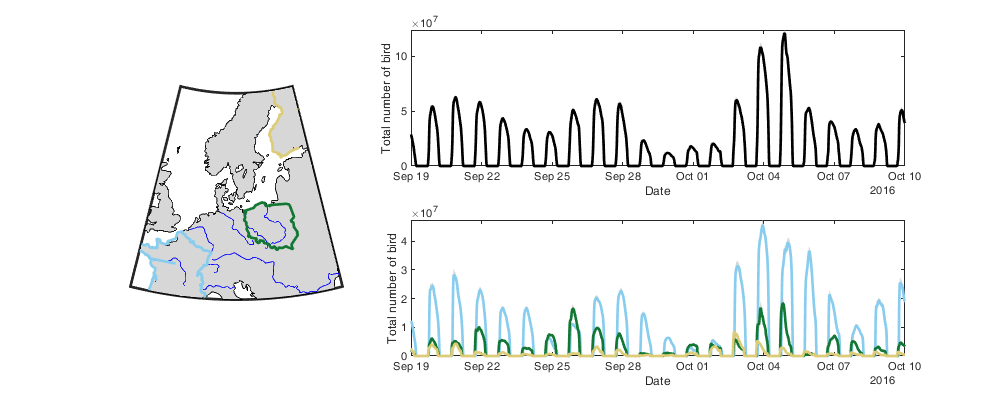

co=[51,34,136;136,204,238;68,170,153;17,119,51;153,153,51;221,204,119;204,102,119;136,34,85;170,68,153]/255;
figure('position',[0 0 1000 400]);
subplot(2,3,[2 3]); hold on;
fill([g.time fliplr(g.time)]', [ssumg(:,10) ; flipud(ssumg(:,90))],[.7 .7 .7],'EdgeColor','none','FaceAlpha',.5)
plot(g.time,mean(ssumg,2),'k','linewidth',2);
xlabel('Date'); ylabel('Total number of bird'); box on
axis tight
subplot(2,3,[5 6]); hold on;
for i_l=1:numel(l)
    fill([g.time fliplr(g.time)]', [ssum(:,10,i_l) ; flipud(ssum(:,90,i_l))],[.7 .7 .7],'EdgeColor','none','FaceAlpha',.5)
    plot(g.time,mean(ssum(:,:,i_l),2),'Color',co(i_l*2,:),'linewidth',2);
end
xlabel('Date'); ylabel('Total number of bird'); box on
axis tight

subplot(2,3,[1 4]); hold on;
h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255)
geoshow('worldrivers.shp','Color', 'blue')
for i_l=1:numel(l)
    plotm(l{i_l}(:,2),l{i_l}(:,1),'Color',co(i_l*2,:),'linewidth',2);
end

Maximum number of bird

[~,id]=max(max(ssumg,[],2));
id=id+2

id = 1527

fprintf('Maximum number of bird aloft: %.2f (%.2f-%.2f) on the %s',ssumg(id,50)/1000000,ssumg(id,10)/1000000,ssumg(id,90)/1000000,datestr(g.time(id)))

Maximum number of bird aloft: 120.00 (116.95-123.36) on the 04-Oct-2016 21:30:00

fprintf('France: %.2f (%.2f-%.2f)',ssum(id,50,1)/1000000,ssum(id,10,1)/1000000,ssum(id,90,1)/1000000)

France: 37.07 (35.59-38.59)

fprintf('Poland: %.2f (%.2f-%.2f)',ssum(id,50,2)/1000000,ssum(id,10,2)/1000000,ssum(id,90,2)/1000000)

Poland: 14.01 (12.87-15.01)

fprintf('Finland: %.2f (%.2f-%.2f)',ssum(id,50,3)/1000000,ssum(id,10,3)/1000000,ssum(id,90,3)/1000000)

Finland: 2.01 (1.87-2.16)

# Supplementary Information

## Figure A1: Cleaning

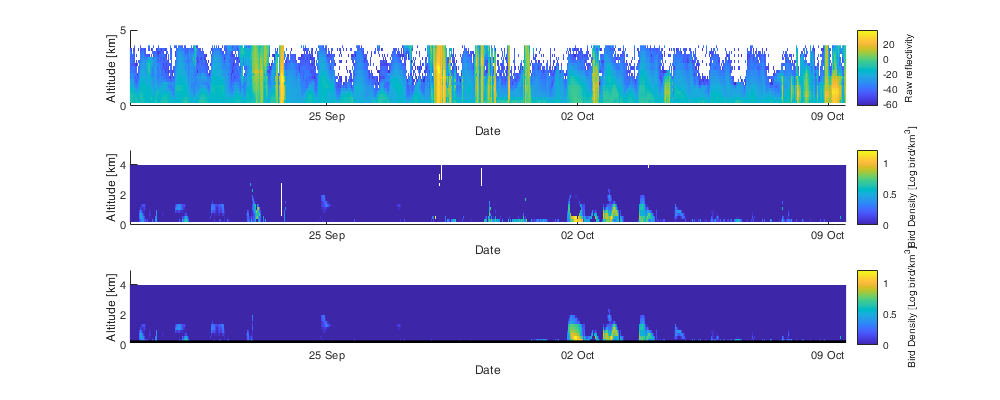

load('../1-Cleaning/data/d.mat');
figure('position',[0 0 1000 400]); 
i_dc=find(strcmp({dc.name},'dedrs'));

for i_dc=1:numel(dc)
    clf;
    i_d=find(strcmp({d.name},dc(i_dc).name));
    subplot(3,1,1); hold on;
    imagesc(datenum(d(i_d).time), d(i_d).interval/1000*(1/2:double(d(i_d).levels)), (d(i_d).DBZH)','AlphaData',~isnan(d(i_d).DBZH'))
    xlabel('Date'); ylabel('Altitude [km]'); c=colorbar; c.Label.String='Raw reflectivity'; %caxis([0 5])
    datetick('x','dd mmm'); axis([datenum(start_date) datenum(end_date-1) 0 5]); set(gca, 'YDir', 'normal')
    
    subplot(3,1,2); hold on;
    imagesc(datenum(d(i_d).time), d(i_d).interval/1000*(1/2:double(d(i_d).levels)), log10(d(i_d).dens)','AlphaData',~isnan(d(i_d).dens'))
    %plot([datenum(start_date) datenum(end_date)],[d(i_d).height d(i_d).height],'r','linewidth',2); caxis([-5 5])
    xlabel('Date'); ylabel('Altitude [km]'); c=colorbar; c.Label.String='Bird Density [Log bird/km^3]'; caxis([0 max(log10(dc(i_dc).dens(:)))])
    datetick('x','dd mmm'); axis([datenum(start_date) datenum(end_date-1) 0 5]); set(gca, 'YDir', 'normal')
    
    subplot(3,1,3); hold on;
    imagesc(datenum(dc(i_dc).time), dc(i_dc).interval/1000*(1/2:double(dc(i_dc).levels)), log10(dc(i_dc).dens)', 'AlphaData',~isnan(dc(i_dc).dens)')
    rectangle('Position',[0 -1 datenum(end_date+2) 1+dc(i_dc).height/1000], 'FaceColor',[1 1 1],'EdgeColor','k','LineWidth',2)
    xlabel('Date'); ylabel('Altitude [km]'); c=colorbar; c.Label.String='Bird Density [Log bird/km^3]'; caxis([0 max(log10(dc(i_dc).dens(:)))])
    datetick('x','dd mmm'); axis([datenum(start_date) datenum(end_date-1) 0 5]); set(gca, 'YDir', 'normal')    
    
    % print(['paper/figure/cleaning/' num2str(i_dc) ,'_', dc(i_dc).name '.png'],'-dpng', '-r300')
end

## Table B1

fprintf('Power transform: %.3f',pow)

Power transform: 0.133

fprintf('Spatial trend: w_0=%.3f, w_{lat}=%.3f',multi.w(1),multi.w(2))

Spatial trend: w_0=2.566, w_{lat}=-0.024

fprintf(['Covariance of $N$: C_0=%.3f, C_{0,0}=%.3f, C_G=%.3f, r_d=%.3f, r_t=%.3f, alpha=%.3f, gamma=%.3f, beta=%.3f'],multi.cov.parm)

Covariance of $N$: C_0=0.001, C_{0,0}=0.006, C_G=0.032, r_d=500.023, r_t=1.124, alpha=0.979, gamma=0.708, beta=0.095

fprintf('%.2f,',intra.a)

0.04,-0.10,0.07,0.27,-1.29,-0.59,2.86,0.44,-1.92,

fprintf('%.2f,',intra.b)

0.00,-0.00,0.02,0.04,-0.17,-0.17,0.62,0.26,-0.93,-0.12,0.49,

fprintf(['Covariance of $I$:C_0=%.3f, C_{0,0}=%.3f, C_G=%.3f, r_d=%.3f, r_t=%.3f, alpha=%.3f, gamma=%.3f, beta=%.3f'],intra.cov.parm)

Covariance of $I$:C_0=0.089, C_{0,0}=0.000, C_G=0.913, r_d=190.394, r_t=0.066, alpha=0.999, gamma=0.403, beta=0.997

## Figure B1: Histogram raw data

disp(['Power transform value: ' num2str(1/pow)])

Power transform value: 7.535


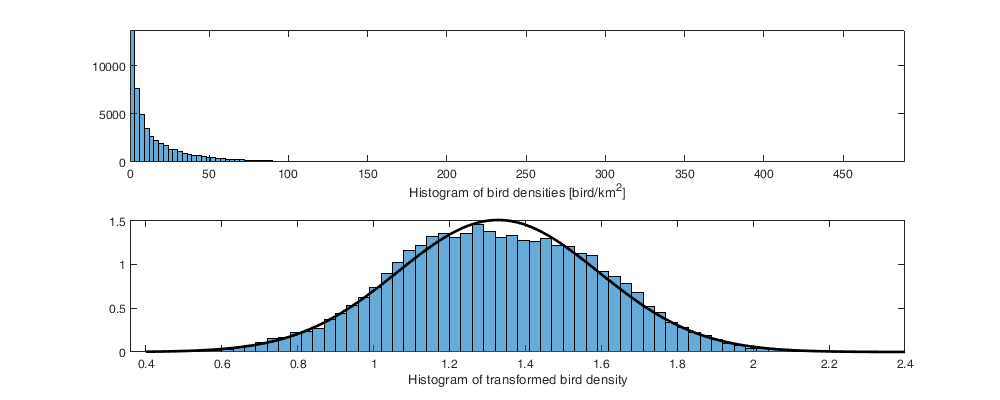

figure('position',[0 0 1000 400]);
subplot(2,1,1)
histogram(data.dens); xlabel('Histogram of bird densities [bird/km^2]'); axis tight;
subplot(2,1,2); hold on; box on;
histogram(data.denst,'Normalization','pdf'); xlabel('Histogram of transformed bird density')
plot(.4:.01:2.4, normpdf(.4:.01:2.4,mean(data.denst), std(data.denst)),'k','linewidth',2);

disp(['Quantile 10%: ' num2str(quantile(data.dens,0.1)) ' and quantile 90%: ' num2str(quantile(data.dens,0.9))])

Quantile 10%: 0.93666 and quantile 90%: 48.176


disp(['Mean: ' num2str(mean(data.dens)) ' and median: ' num2str(median(data.dens))])

Mean: 18.6384 and median: 8.265


## Figure B2: Trend

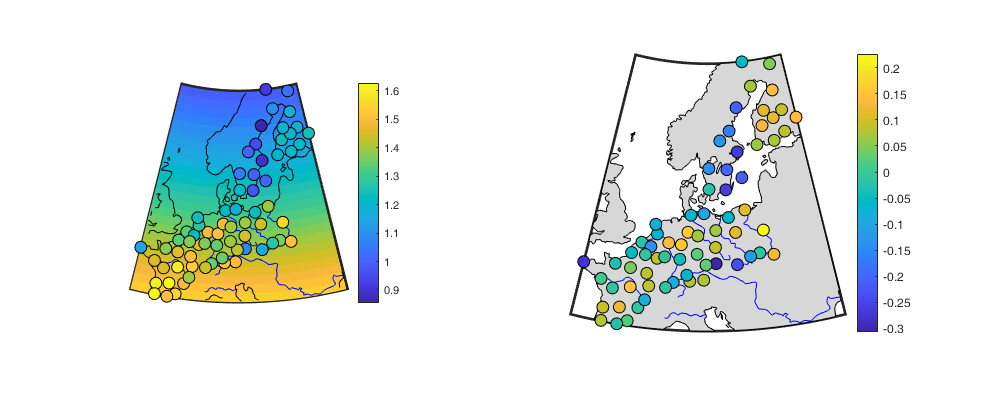

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
[LAT,LON] = meshgrid(min([dc.lat]):max([dc.lat]),min([dc.lon]):max([dc.lon]));
surfm(LAT,LON,LAT*multi.w(2)+multi.w(1))
plotm(coastlat, coastlon,'k')
geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],80,nanmean(multi.A,2),'filled','MarkerEdgeColor','k'); %title('fitted planar trend with average of radar'); 
colorbar

% subplot(1,3,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
% geoshow('landareas.shp', 'FaceColor', [0.5 0.7 0.5])
% geoshow('worldrivers.shp','Color', 'blue')
% scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,S,'filled','MarkerEdgeColor','k'); %title('fitted planar trend with average of radar'); 

subplot(1,2,2); h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],80,nanmean(multi.A,2)-[dc.lat]'*multi.w(2)-multi.w(1),'filled','MarkerEdgeColor','k'); % title('Residual average of radar');
colorbar

## Figure B3: Curve

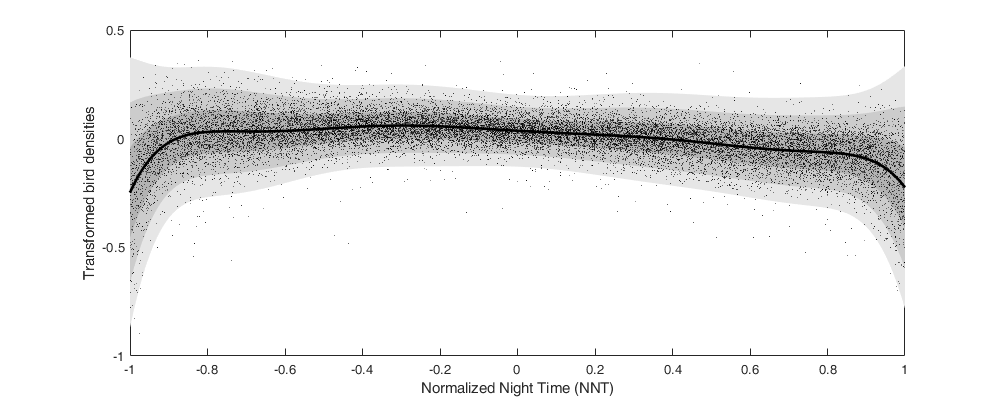

figure('position',[0 0 1000 400]);   hold on;
NNT_axis=(-1:.01:1)';
y=bsxfun(@power,NNT_axis,0:intra.apo)*intra.a;
z=sqrt(bsxfun(@power,NNT_axis,0:intra.bpo)*intra.b);

fill([NNT_axis ; flipud(NNT_axis)], [y-3*z ; flipud(y+3*z)],[.9 .9 .9],'EdgeColor','none')
fill([NNT_axis ; flipud(NNT_axis)], [y-2*z ; flipud(y+2*z)],[.8 .8 .8],'EdgeColor','none')
fill([NNT_axis ; flipud(NNT_axis)], [y-1*z ; flipud(y+1*z)],[.7 .7 .7],'EdgeColor','none')
plot(data.NNT(1:2:end),intra.R(1:2:end),'.k','MarkerSize',0.5);
plot(NNT_axis,y,'-k','linewidth',2)
xlabel('Normalized Night Time (NNT)'); ylabel('Transformed bird densities');  box on;

## Figure B4: Covariance

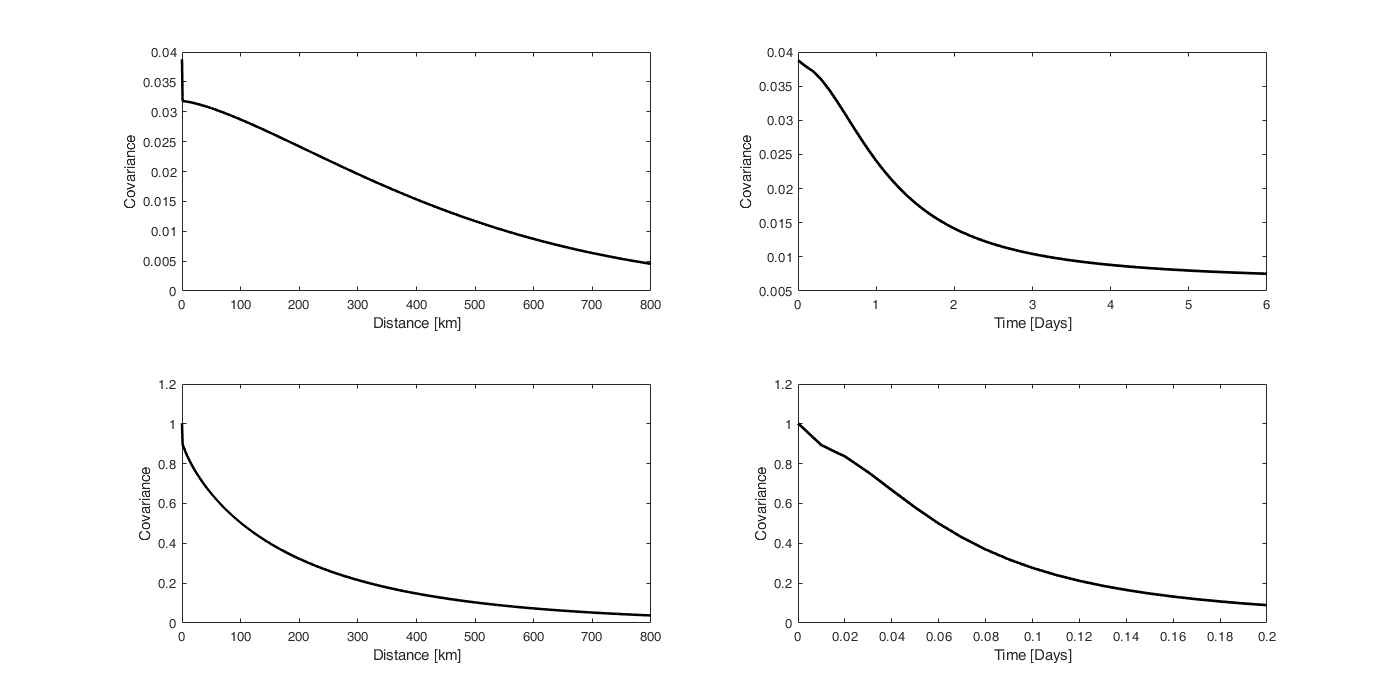

tmpD = multi.cov.d(1):1:multi.cov.d(end);
tmpT = multi.cov.t(1):0.1:multi.cov.t(end);

fig7=figure('position',[0 0 1400 700]);
subplot(2,2,1); hold on
plot(tmpD,multi.cov.C(tmpD, zeros(size(tmpD))),'-k','linewidth',2);
%plot(multi.cov.D(1,:),multi.cov.emp_grid(1,:),'xr')
xlabel('Distance [km]'); ylabel('Covariance'); box on; xlim([0 800])
subplot(2,2,2); hold on
plot(tmpT,multi.cov.C(zeros(size(tmpT)), tmpT),'-k','linewidth',2);
%plot(multi.cov.T(:,1),multi.cov.emp_grid(:,1),'xr')
xlabel('Time [Days]'); ylabel('Covariance'); box on; xlim([0 6])

%fig6=figure('position',[0 0 1400 700]); 
tmpD = intra.cov.d(1):1:intra.cov.d(end);
tmpT = intra.cov.t(1):0.01:intra.cov.t(end);
subplot(2,2,3); hold on
plot(tmpD,intra.cov.C(tmpD, zeros(size(tmpD))),'-k','linewidth',2);
%plot(intra.cov.D(1,:),intra.cov.emp_grid(1,:),'xr')
xlabel('Distance [km]'); ylabel('Covariance'); box on; xlim([0 800])
subplot(2,2,4); hold on
plot(tmpT,intra.cov.C(zeros(size(tmpT)), tmpT),'-k','linewidth',2);
%plot(intra.cov.T(:,1),intra.cov.emp_grid(:,1),'xr')
xlabel('Time [Days]'); ylabel('Covariance'); box on; xlim([0 0.2])

## Figure C1: Kriging estimation

latlonmask = find(g.latlonmask);
Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
wradius=4;

i_l=round(g.nlm/3);
id1=find(gmulti.Ddist_sf(:,latlonmask(i_l))<multi.cov.parm(3)*wradius);
i_t=g.nat/2;
id2= id1(gmulti.Dtime_sf(id1,i_t)<multi.cov.parm(4)*wradius);
Cab = multi.cov.parm(2).*Gneiting(gmulti.Ddist_sf(id2,latlonmask(i_l)), gmulti.Dtime_sf(id2,i_t), multi.cov.parm(3), multi.cov.parm(4), multi.cov.parm(5), multi.cov.parm(6), multi.cov.parm(7));
lambda = multi.cov.C(id2,id2)  \  Cab;
An_est = lambda' * multi.An(id2);
An_sig = sqrt(multi.cov.parm(1) + multi.cov.parm(2) - lambda' * Cab);

figure; hold on;
idisnan=find(~multi.isnanA);
[I_d, I_t]=ind2sub(size(multi.A),idisnan(id2));
plot3( coastlon,coastlat, min(g.atime(I_t))*ones(size(coastlon)),'k','linewidth',1)
fill3( coastlon,coastlat, min(g.atime(I_t))*ones(size(coastlon)),'k')
plot3( coastlon,coastlat, 0.5*(max(g.atime(I_t))+min(g.atime(I_t)))*ones(size(coastlon)),'k','linewidth',0.5)
plot3( coastlon,coastlat, max(g.atime(I_t))*ones(size(coastlon)),'k','linewidth',.5)
dc_lat=[dc.lat]; dc_lon=[dc.lon];
scatter3(g.lon2D(latlonmask(i_l)),g.lat2D(latlonmask(i_l)),g.atime(i_t),'r','filled')
scatter3(dc_lon(I_d),dc_lat(I_d),g.atime(I_t),[],real(log10(lambda)),'filled')
ylim([min(dc_lat(I_d))-3 max(dc_lat(I_d))])
xlim([min(dc_lon(I_d))-3 max(dc_lon(I_d))+2]); 
zlim([min(g.atime(I_t)) max(g.atime(I_t))])
view(3); box on; ylabel('Latitude'); xlabel('Longitude'); zlabel('Time '); datetick('z','dd-mmm','keeplimits')
colorbar('southoutside');
%set(gca,'BoxStyle','full'); 
grid on

## Figure D1

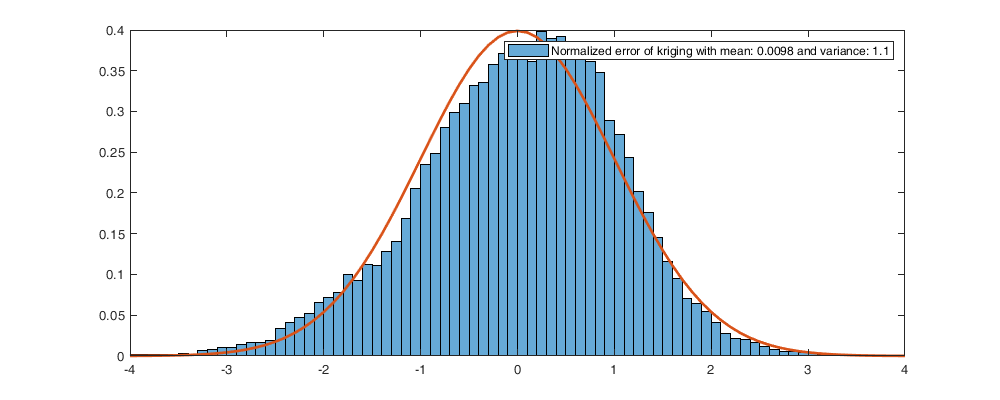

figure('position',[0 0 1000 400]); histogram( cv.nee,'Normalization','pdf' );
hold on; plot(-4:.1:4,normpdf(-4:.1:4),'linewidth',2)
legend(['Normalized error of estimation with mean: ' num2str(nanmean(cv.nee),1) ' and variance: ' num2str(nanvar(cv.nee),3)]);
xlim([-4 4])

## Figure D2

% figure('position',[0 0 1000 400]);
% % boxplot(cv.nee,data.radar,'Symbol','.k');ylim([-4 4])
% errorbar(1:69,splitapply(@mean,cv.nee,data.radar),splitapply(@var,cv.nee,data.radar),'.k');ylim([-3 3])
% xticklabels({dc.name}); xtickangle(90); 

## Figure D3: Map of normalized error of estimation per radar

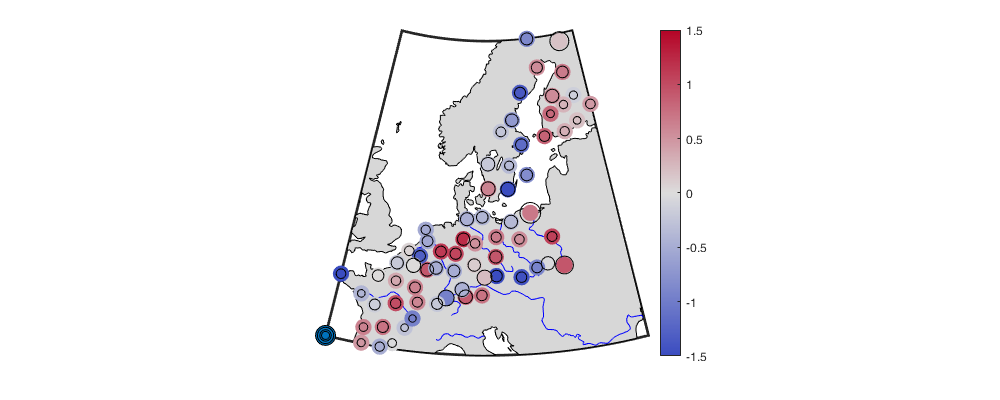

figure('position',[0 0 1000 400]); hold on
h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],150,splitapply(@mean,cv.nee,data.radar),'filled'); 
scatterm([dc.lat],[dc.lon],150+150*(splitapply(@var,cv.nee,data.radar)-1),'MarkerEdgeColor','k'); 
scatterm(min([dc.lat])*[1 1 1 1],min([dc.lon])*[1 1 1 1],150+150*([1.5 1 0.5 0.25]-1),'filled','MarkerEdgeColor','k'); 
colormap(interp1([0 .5 1],[0.230, 0.299, 0.754;0.865, 0.865, 0.865;0.706, 0.016, 0.150],linspace(0,1,254)));
colorbar; caxis([-1.5 1.5])

## Figure D4: bird densities estimated and observed with uncerttainty range for

Either all (for loop), dropbown (only available on livescript) or select a central one. 

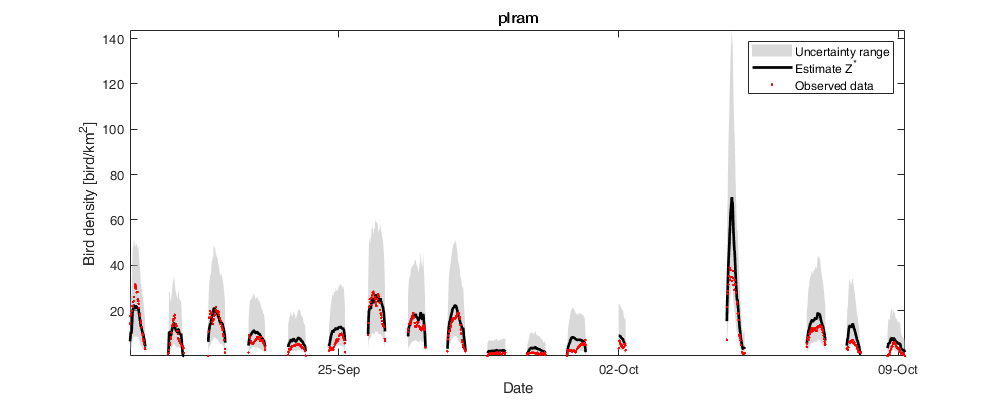

% for i_r=1:numel(dc)

[~,tmp] = sort( abs(splitapply(@mean,cv.nee,data.i_r)) + abs(splitapply(@var,cv.nee,data.i_r)-1));
i_r = tmp(round(end/2));

i_name ='plram';
i_r = find(strcmp(i_name,{dc.name}));

t = data.time(data.i_r==i_r)';
e = ( cv.denst_est(data.i_r==i_r) ).^(1/pow);
tmp1 = ( cv.denst_est(data.i_r==i_r)+norminv(.1).*cv.denst_sig(data.i_r==i_r) ).^(1/pow);
tmp2 = ( cv.denst_est(data.i_r==i_r)+norminv(.9).*cv.denst_sig(data.i_r==i_r) ).^(1/pow);

ix = [0 find(diff(t)>1/24*4) numel(t)];

figure('position',[0 0 1000 400]); hold on
for i_x=1:numel(ix)-1
    id=(ix(i_x)+1):ix(i_x+1);
    h1=fill([t(id) fliplr(t(id))]', [tmp1(id) ; flipud(tmp2(id))],[.7 .7 .7],'EdgeColor','none','FaceAlpha',.5);
    h2=plot(t(id),e(id),'k','linewidth',2);
end
h3=plot(t,data.dens(data.i_r==i_r),'.r');
axis tight; % ylim([0 max(data.dens(data.i_r==i_r))])
box on; ylabel('Bird density [bird/km^2]'); xlabel('Date');datetick('x','dd-mmm','keeplimits')
legend([h1,h2,h3],'Uncertainty range','Estimate Z^*','Observed data'); title(dc(i_r).name)

%     print(['paper/figure/cross_valid/radar' num2str(i_r) '.png'],'-dpng', '-r600')
%     print(['paper/figure/cross_valid/radar' num2str(i_r) '_vec.eps'],'-depsc', '-r300', '-painters')
% end